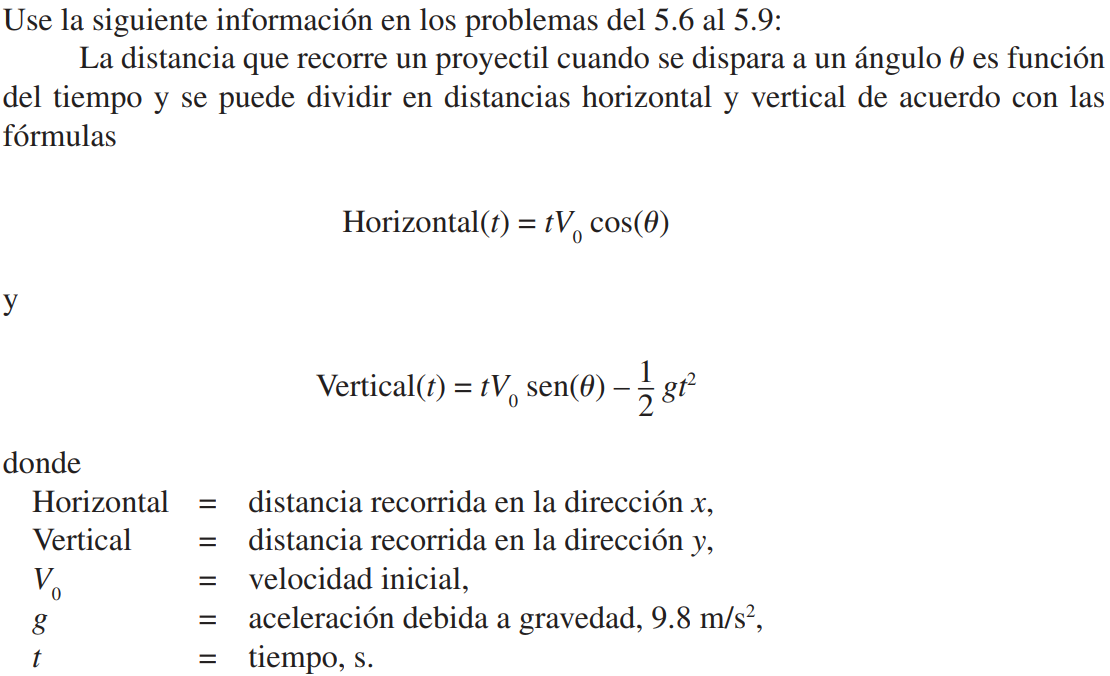

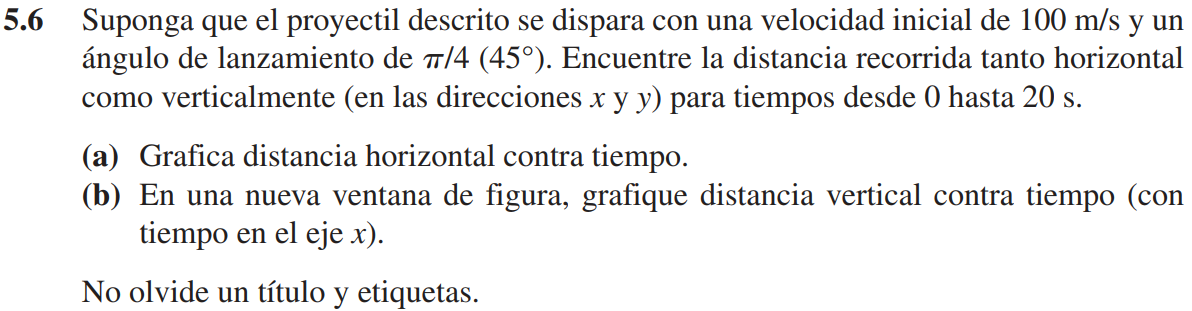

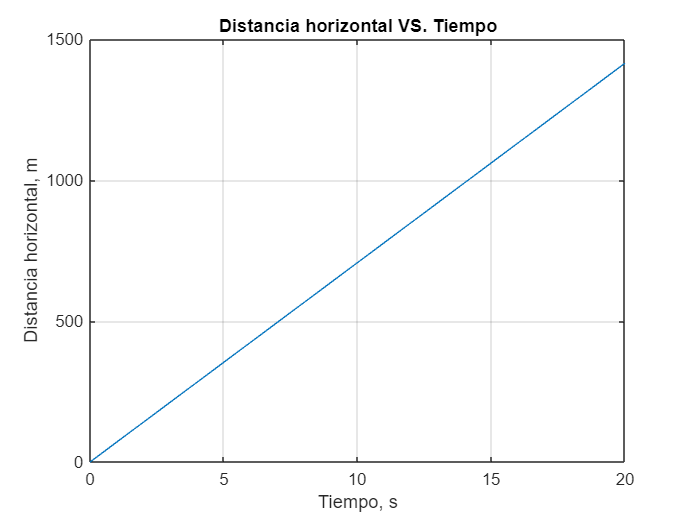

clear

g = 9.8;
v0 = 100;
ang = deg2rad(45);
t = 0:20;
x = v0*t*cos(ang);
y = v0*t*sin(ang) - .5*g*t.^2;

% Literal (a).
plot(t,x)
    title 'Distancia horizontal VS. Tiempo'
    xlabel 'Tiempo, s'
    ylabel 'Distancia horizontal, m'
    grid

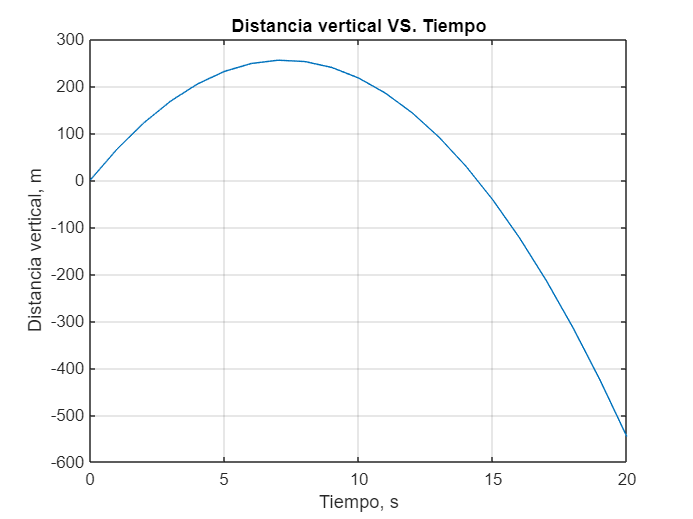


% Literal (b).
plot(t,y)
    title 'Distancia vertical VS. Tiempo'
    xlabel 'Tiempo, s'
    ylabel 'Distancia vertical, m'
    grid

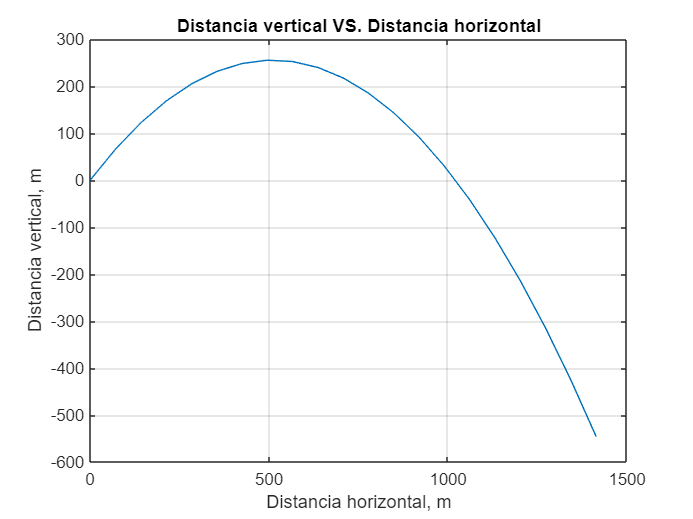

plot(x,y)
    title 'Distancia vertical VS. Distancia horizontal'
    xlabel 'Distancia horizontal, m'
    ylabel 'Distancia vertical, m'
    grid

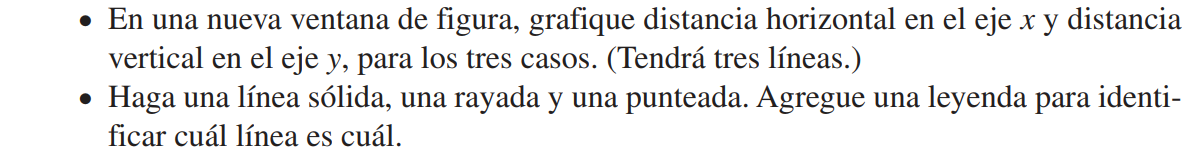

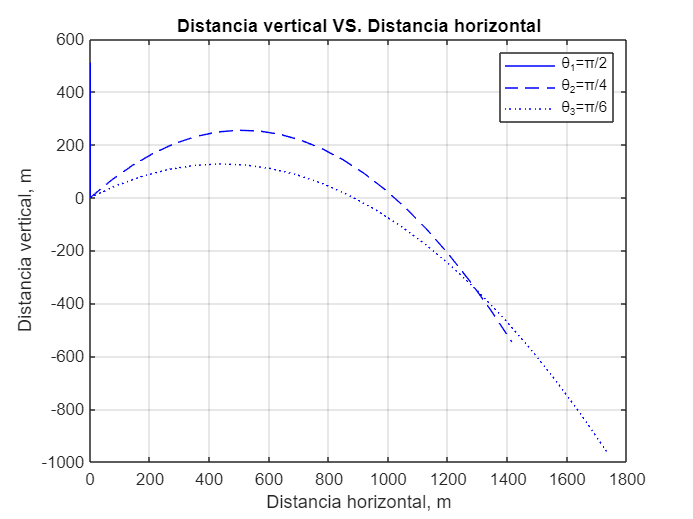

ang1 = pi/2;
ang2 = pi/4;
ang3 = pi/6;
x1 = v0*t*cos(ang1);
x2 = v0*t*cos(ang2);
x3 = v0*t*cos(ang3);
y1 = v0*t*sin(ang1) - .5*g*t.^2;
y2 = v0*t*sin(ang2) - .5*g*t.^2;
y3 = v0*t*sin(ang3) - .5*g*t.^2;

plot(x1,y1,'-b',x2,y2,'--b',x3,y3,':b')
    title 'Distancia vertical VS. Distancia horizontal'
    xlabel 'Distancia horizontal, m'
    ylabel 'Distancia vertical, m'
    legend('\theta_{1}=\pi/2','\theta_{2}=\pi/4','\theta_{3}=\pi/6')
    grid

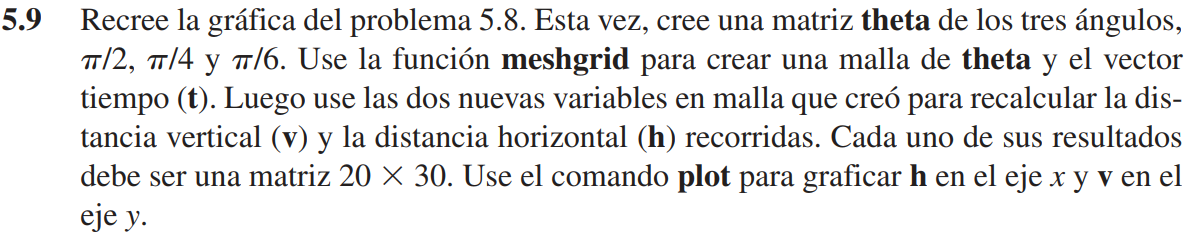

En lugar de dar como primer argumento **theta** a la función `meshgrid`, se ingresará directamente el `seno` y `coseno`.

theta = [ang1 ang2 ang3];
[cos_theta, T] = meshgrid(cos(theta),t);
[sin_theta, T] = meshgrid(sin(theta),t);

x = v0*T.*cos_theta

x = 	1.0e+03 *

         0         0         0
    0.0000    0.0707    0.0866
    0.0000    0.1414    0.1732
    0.0000    0.2121    0.2598
    0.0000    0.2828    0.3464
    0.0000    0.3536    0.4330
    0.0000    0.4243    0.5196
    0.0000    0.4950    0.6062
    0.0000    0.5657    0.6928
    0.0000    0.6364    0.7794


y = v0*T.*sin_theta - .5*g*T.^2

y =          0         0         0
   95.1000   65.8107   45.1000
  180.4000  121.8214   80.4000
  255.9000  168.0320  105.9000
  321.6000  204.4427  121.6000
  377.5000  231.0534  127.5000
  423.6000  247.8641  123.6000
  459.9000  254.8747  109.9000
  486.4000  252.0854   86.4000
  503.1000  239.4961   53.1000


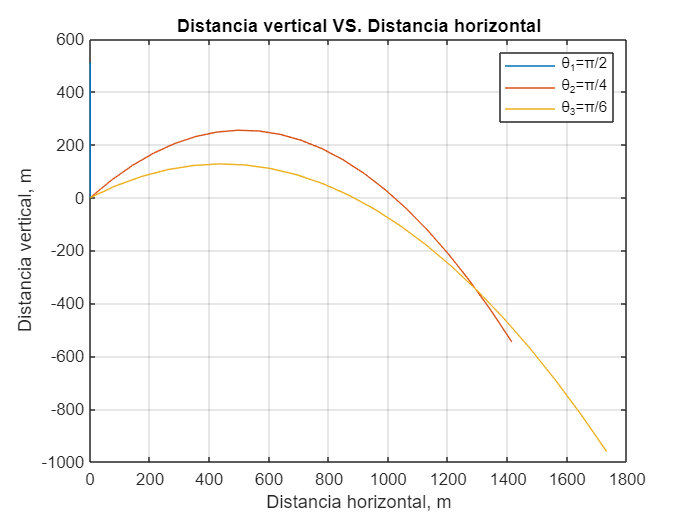

plot(x,y)
title 'Distancia vertical VS. Distancia horizontal'
    xlabel 'Distancia horizontal, m'
    ylabel 'Distancia vertical, m'
    legend('\theta_{1}=\pi/2','\theta_{2}=\pi/4','\theta_{3}=\pi/6')
    grid